# Companion MATLAB Live Script for *A Survey of Methods for the Discretization of Phonograph Record Playback Filters *

Presented at the 157th Convention of the Audio Engineeering Society (AES) in New York City, New York, 2024

Authors: Benjamin R Thompson and Tre DiPassio

Link to the Paper: [https://aes.org/publications/elibrary-page/22694.pdf](https://aes.org/publications/elibrary-page/22694.pdf)

The sections labeled as "Interactive" are meant to walk the reader through the various methods for discritization that are defined in the paper. **As you read through the script, press the buttons to execute the code and see the results. **It is recommended to view this live script in "Output Inline" mode except where notated.

## 1) Introduction

As mentioned in Section 1 of the paper, almost all electrically recorded records are cut with some equalization that allows the cutter to switch between a constant-velocity response and a constant-amplitude response for different bands within the audible spectrum. For laterally-cut grooves, this allows for grooves that take up less space and thus more information for a given area. If equalization is applied to a record when it is cut, an inverse equalization must be applied on playback to recover a flat frequency response. Since approximately 1954, the RIAA curve has been the standard equalization curve used to cut most records. The playback curve for records cut with the RIAA standard is depicted in by trace E below, modified from Moyer (Paper Reference [[10]](https://www.aes.org/aeshc/pdf/moyer_evolution-of-a-recording-curve.pdf)):

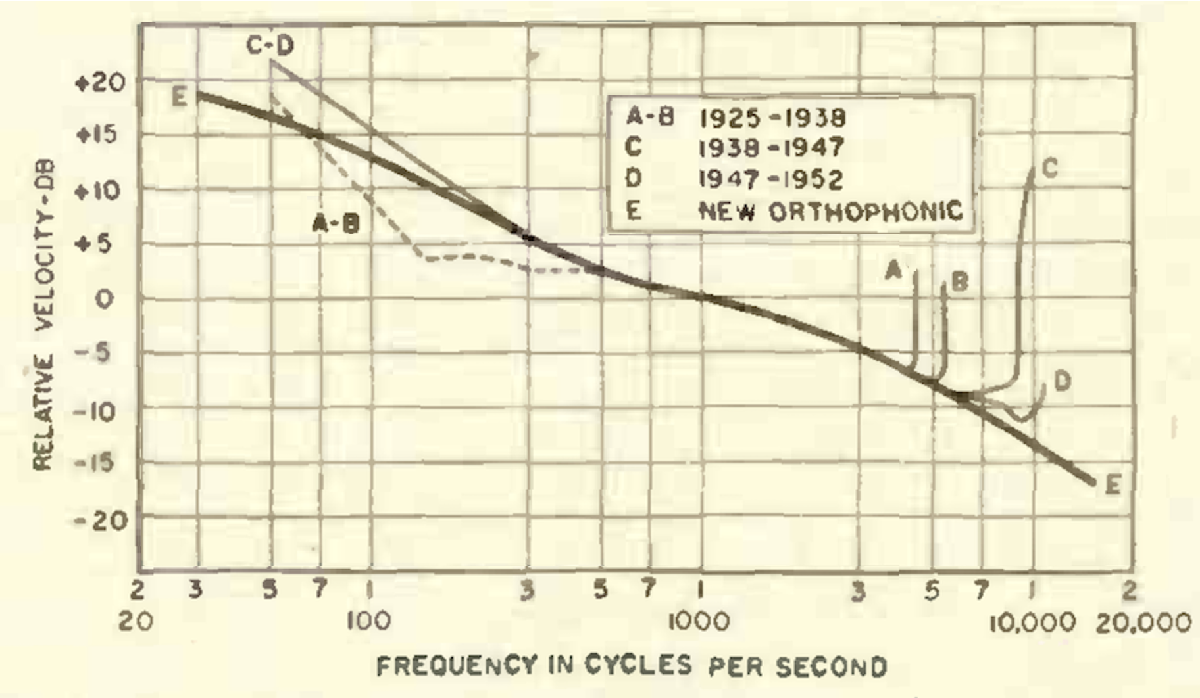

The RIAA standard curve is defined by three time constants that determine the curve's treble rolloff, bass boost, and bass shelving frequencies. Many playback curves are defined by three time constants, though older curves may require as few as a single time constant which would describe the turnover frequency for the bass boost. Most phonograph playback devices made after 1954 include analog circuity to apply the curve from the figure above. An example of a phono preamplifier with integrated RIAA playback equalization is depicted below. If you analyzed or simulated this circuit (Reproduced directly from *Small Signal Audio Design *by Douglas Self - paper reference [[11]](http://www.douglas-self.com/ampins/books/ssad3.htm)), you would get a transfer function that looked identical to the RIAA playback curve form trace E in the image above:

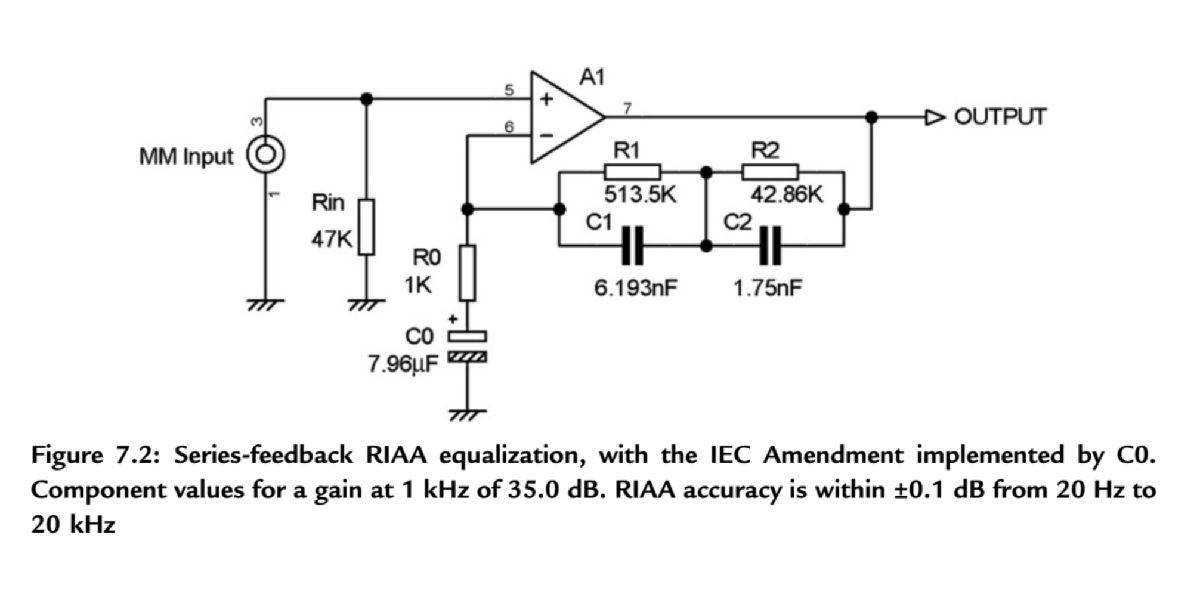

Before the adoption of the RIAA standard, the required playback curve for a disc could vary over time and from record company to record company. Therefore, anyone seeking to hear or restore the information from older discs must have access to multiple playback curves. This correction may be accomplished with either analog hardware or digital processing. The digital approach has the advantages of reduced cost and expanded versatility, but requires a transformation from continuous time, where the original curves are defined, to discrete time. This transformation inevitably comes with some deviations from the continuous-time response near the Nyquist frequency. There are many established methods for discretizing continuous-time filters, and these vary in performance, computational cost, and inherent latency. 

In the paper and in this MATLAB Live Script, we impliment several methods for performing this transformation in the context of phonograph record playback equalization. This script is intented to serve as a resource for anyone developing systems for digital playback equalization or similar applications that require approximating the response of a continuous-time filter digitally. The intention is by no means to declare a "winner", even for this specific application. Instead, it is meant to quantify some of the compromises of different approaches to discretization in a way that might be useful to those who find themselves developing systems for digital playback equalization or other applications where it is necessary to mimic an analog response in the digital domain.

## 2) Continuous Time RIAA System

In this MATLAB Live Script, we will use the RIAA playback equalization curve as a prototype filter to compare the various filter discretization methods. What is now known as the RIAA curve was developed by RCA Victor as the "New Orthophonic" curve and was published in 1953 (see paper reference [[10]](https://www.aes.org/aeshc/pdf/moyer_evolution-of-a-recording-curve.pdf)). This curve was adopted as a standard by a number of recording and broadcast organizations including the Recording Industry Association of America, eventually becoming a universal standard applied to all microgroove records (see paper reference [[7]](https://www.collinsaudio.com/Prosound_Workshop/Analogue%20Sound%20Restoration.pdf)). 

The original RIAA playback curve is defined by three time constants:

T0 = 318e-6;  % time constant for bass boost, in seconds
T1 = 75e-6;   % time constant for treble roll-off, in seconds
T2 = 3180e-6; % time constant for bass shelf, in seconds

The transfer function for this filter as defined by these time constants, with a gain factor applied such that the magnitude response at 1 kHz is approximately equal to 0 dB, can be written as follows (equation 2 from the paper):

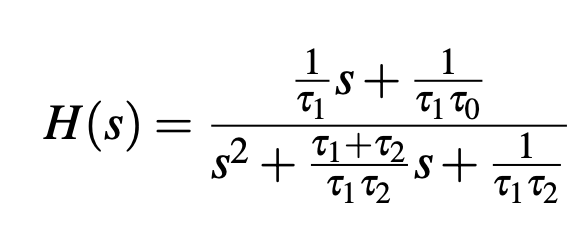	

We can represent the numerator and denominator of this transfer function in MATLAB as follows:

b0 = [0 1/T1 1/(T1*T0)];                % continuous time numerator 
a0 = [1 (T1+T2)/(T1*T2) 1/(T1*T2)];     % continuous time denominator 

We can then use MATLAB's tf function to make a continuous time transfer function object:

 

sdtf = tf(b0, a0) % make continuous transfer function object


sdtf =
 
     1.333e04 s + 4.193e07
  ---------------------------
  s^2 + 1.365e04 s + 4.193e06
 
Continuous-time transfer function.


As seen above, the s-domain transfer function (*sdtf*) varible is a continuous time transfer function which stores the numerator and denominator of the RIAA inverse filter using *s* as the complex variable. 

Let's first ensure that the response of this transfer function looks like the original inverse RIAA filter shown in Section 1 of this MATLAB Live Script. We can do this by performing an FFT with 'freqs' to generate a sampled frequency response.

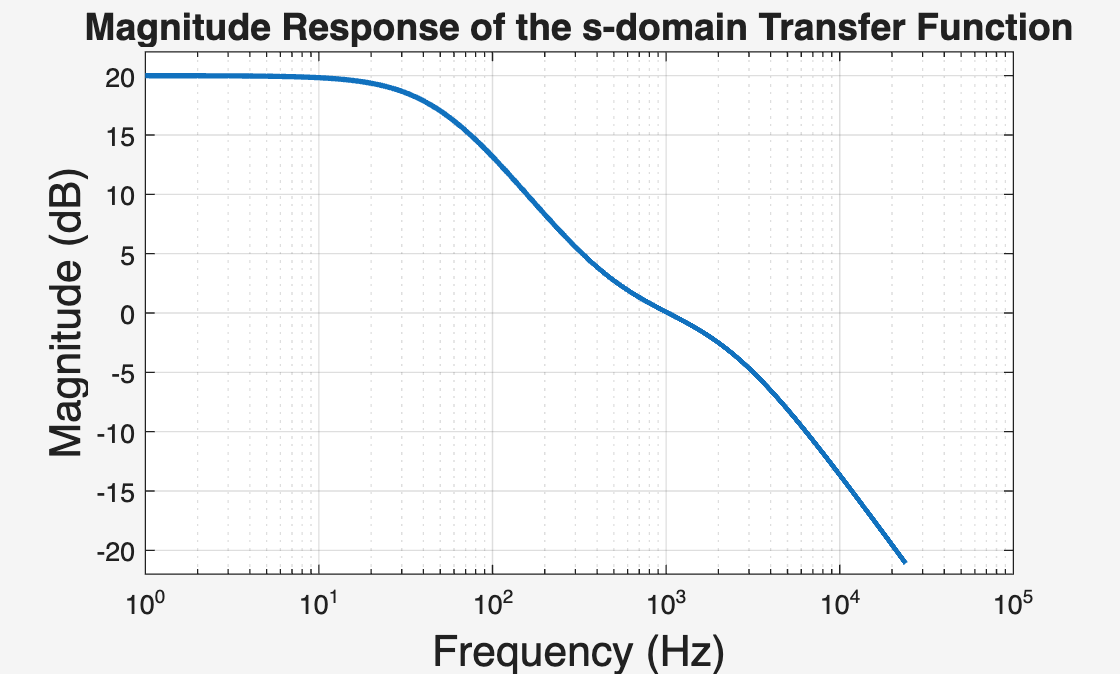

 

% Define the sampling rate (and sample period), which will be used throughout the Live Script:
fs = 48e3;  % Original sample rate of 48kHz
T = 1/fs;   % Original sample period

% Make a frequency array that has 1Hz resolution regardless of sample rate 
f = (0:fs/2-1)';
% Use the frequency array to make an array with units of radians/second:
radPerSec = (2*pi*f); 
% and divide the sampling rate to achieve an array with units of
% radians/sample:
radPerSample = radPerSec/fs;

% Use MATLABs 'freqs' function to make a complex freq response of s-domain
% transfer function using the numerator and denominator of the RIAA filter
H0 = freqs(b0,a0,radPerSec);

% Show that H0 looks like the inverse RIAA curve shown in Section 1 of this
% MATLAB Live Script:

analogResponseFig = figure(1);
analogResponseAxes = axes(analogResponseFig);
set(analogResponseFig, 'CurrentAxes', analogResponseAxes)
set(0, 'CurrentFigure', analogResponseFig)
semilogx(radPerSec/(2*pi),mag2db(abs(H0)),'LineWidth',2);
xlabel('Frequency (Hz)','FontSize',16);
ylabel('Magnitude (dB)','FontSize',16);
title('Magnitude Response of the s-domain Transfer Function','FontSize',14)
grid on
ylim([-22 22])
set(analogResponseFig,'Visible','on')

This response does match the inverse RIAA curve shown in Section 1 of this MATLAB Live Script! 

In addtion to analyzing the frequency repsonse of the analog filter and the discritized version, we will want to examine the time-domain reponses of each version. To that end we will now generate the impulse response of the s-domain filter.

duration = 0.5; % length of the impulse response in seconds. 

% Create a time vector from 0 seconds to through the duration specified
% above in seconds:
t = 0:T:duration-T;

% Make a sampled IR from sdtf:
[h0, ~] = impulse(sdtf,t);

You might notice that *h0* is here is a digital FIR filter that could be applied through **convolution** in the time domain to create a response that is identical to the s-domain tranfer funtion at the sampled frequency intervals (for that matter we could use *H0 *through multiplication in the frequency domain in much the same way). You might ask why we won't just use it directly instead of bothering with the other discretization methods presented here. The answer is that this FIR filter is not **order-preserving**, in that it requires convolution with an FIR filter with a length in samples of *duration * fs* to perform the equalization. 

FIRLength = length(h0)

FIRLength = 24000

Notice here that the numerator and denominator of the continuous time filter both have an original order of 2:

bOrderOriginal = length(b0)-1 % order of s-domain numerator 

bOrderOriginal = 2

aOrderOriginal = length(a0)-1 % order of s-domain denominator 

aOrderOriginal = 2

Instead, we want to create an **order-preserving**, infinite impulse response (IIR) filter. To match the s-domain transfer function, we want to produce a digitized, z-domain IIR filter with the same order as the continuous time system. The methods shown in this script will produce these second-order IIR filters, and allow an exploration of the advantages and trade-offs of each method.

## 3) Selecting Transform for Analysis - Interactive

Select a discretization method below to analyze when running the rest of the script. It is our recommendation to try each method, and compare their accuracies in repdocuding the inverse RIAA filter in both the magnitude and frequency domains

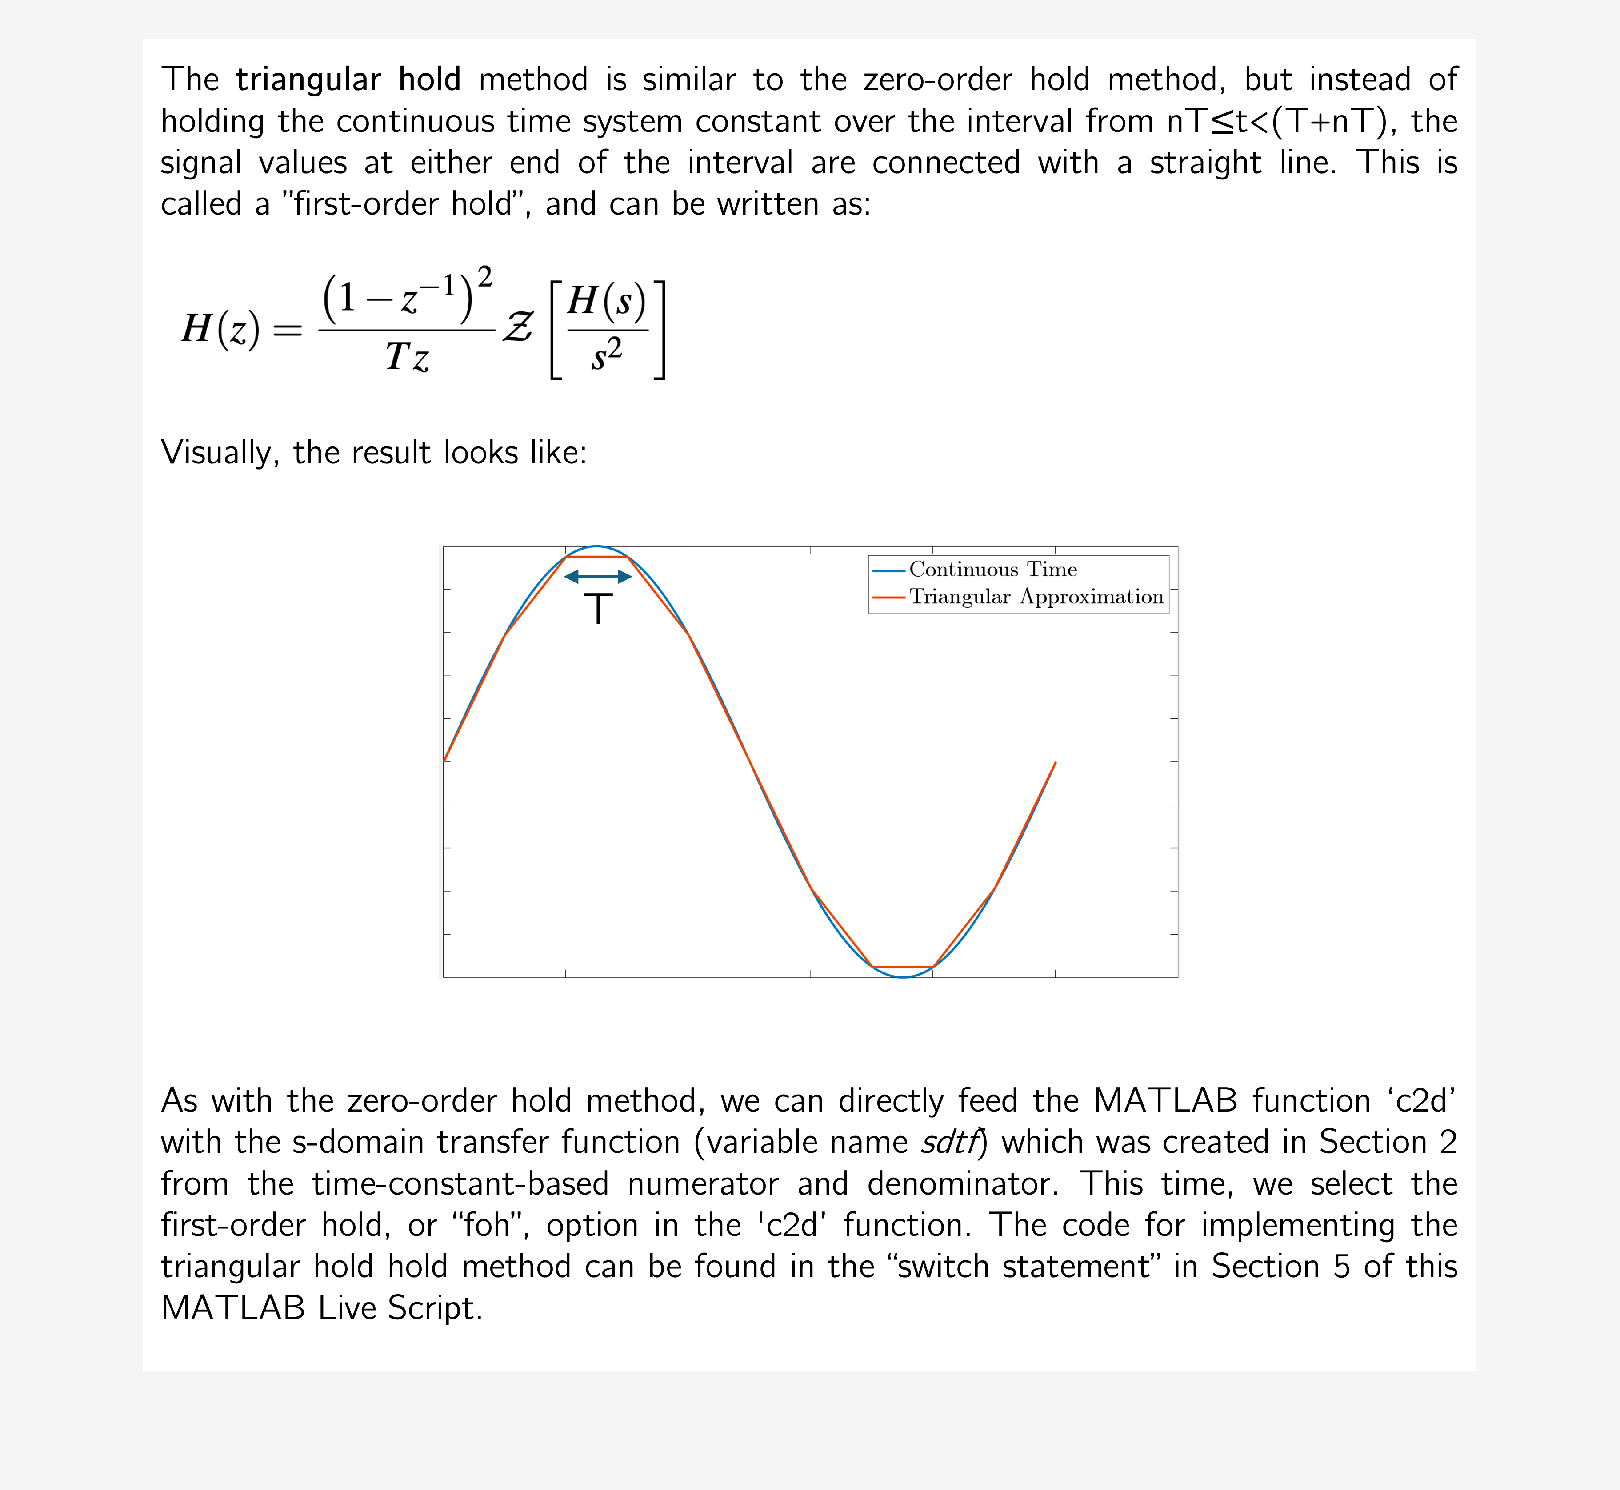

transformMethod = 1;
 
close all
im = userFeedback(transformMethod);
methodFig = figure(2);
set(0, 'CurrentFigure', methodFig)
imshow(im);
set(methodFig,'Visible','on')

## 4) Oversampling - Interactive

The accuracy of most of the discretization methods presented in this MATLAB Live Script can be improved by **oversampling**. As stated in the paper, many of the inaccuracies that arise when using these discretization methods occur near the Nyquist frequency (for a sampling frequency of 48,000 samples per second, the Nyquist frequency is 24 kHz, which is near the audible band). When oversampling, you effectively raise the Nyquist frequency of the signal. When you process the oversampled signal, you wind up with inaccuracies near the *new* Nyquist frequency, though this frequency is now well outside the audible band, and will be filtered out when **downsampling** back to the original sampling rate. The impact of oversampling was demonstrated in the paper in Figure 2 for the Zero-Pole Matching method:

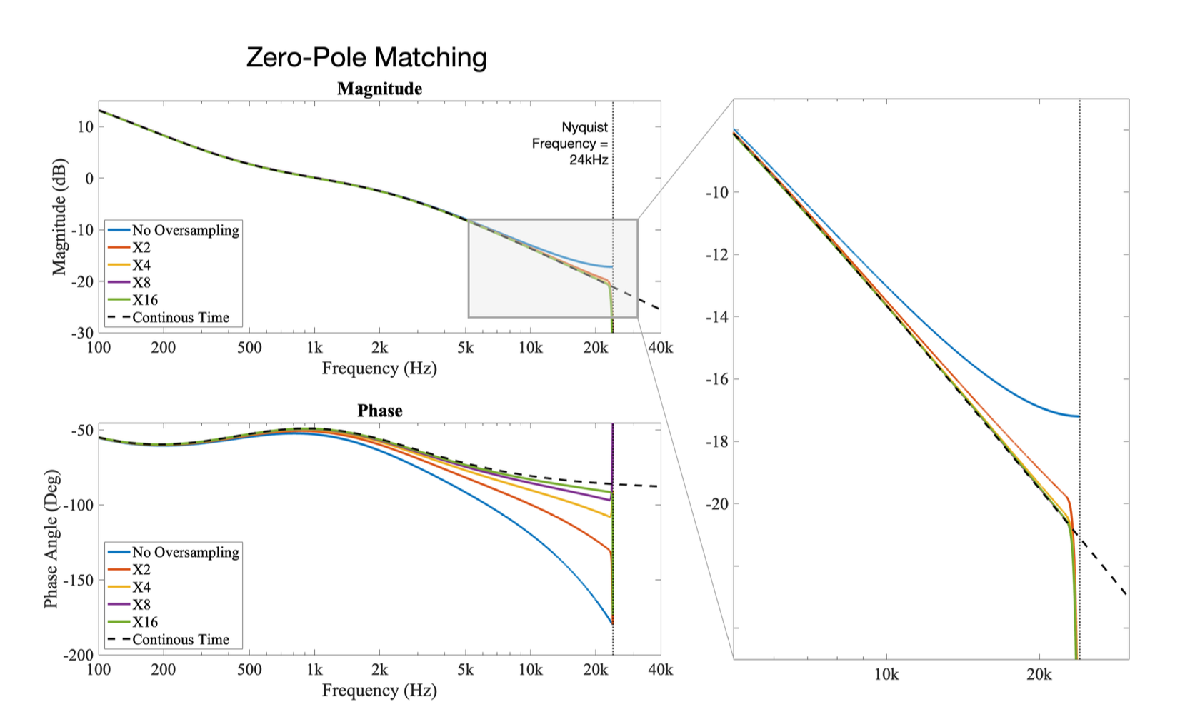

It is our reccomendation to try many values of oversampling for the provided discritization methods to see the effect that oversampling has on the accuracy of the each method.

%%%%%%%%%%%%%%%% Setup Oversampling %%%%%%%%%%%%%%%%%%%
overSampleFactor = 1;  
 
overSampleExp = log2(overSampleFactor);      % Oversampling exponent - upsample rate will be 2^overSampleExp*fs
fsUp = fs*2^overSampleExp;                   % Upsample rate based on the oversampling exponent
Tup = 1/fsUp;                                % Upsample period
[upFilts, downFilts] = getOverSamplingFilters(overSampleExp); % Get anti-alias/image filters, the verbose output is printed below:
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## 5) Processing - Interactive

Here, we impliment the discritization methods based on the option that is selected in Section 3 of this MATLAB Live Script:

 
%%%%%%%%%%%%%%%%%% Transforms %%%%%%%%%%%%%%%%%%%%
switch transformMethod
    case 0
        tic % start timer
        zdtf = c2d(sdtf,Tup,'zoh'); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Zero-Order Hold';
        b1 = zdtf.Numerator{1}; % discrete-time numerator 
        a1 = zdtf.Denominator{1}; % discrete-time denominator        
    case 1
        tic % start timer
        zdtf = c2d(sdtf,Tup,'foh'); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Triangle Approximation';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; % discrete-time numerator 
        a1 = zdtf.Denominator{1}; % discrete-time denominator  
    case 2
        Tup = 1/fsUp; % sample period at upsample rate
        tic % start timer
        zdtf = c2d(sdtf,Tup,'impulse'); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Impulse Invariant';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; % discrete-time numerator 
        a1 = zdtf.Denominator{1}; % discrete-time denominator  
    case 3
        tic % start timer
        zdtf = c2d(sdtf,Tup,'tustin'); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Bilinear Transform';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; % discrete-time numerator 
        a1 = zdtf.Denominator{1}; % discrete-time denominator     
    case 4
        tic % start timer
        zdtf = c2d(sdtf,Tup,'matched'); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Zero-Pole Matching';
        % discrete time coefficients 
        b1 = zdtf.Numerator{1}; % discrete-time numerator 
        a1 = zdtf.Denominator{1}; % discrete-time denominator     
    case 5
        fUp = (0:fsUp/2-1)'; % 1Hz resolution regardless of sample rate 
        radPerSecUp = (2*pi*fUp); % rad/second array
        radPerSampleUp = radPerSecUp/fsUp; % rad/sample array
        H0Up = freqs(b0,a0,radPerSecUp); % complex freq response of s-domain transfer function sampled at upsample rate
        wts = getBkWts((0:fsUp/2-1)'); % weights
        tic % start timer
        [b1,a1] = invfreqz(H0Up,radPerSampleUp,bOrderOriginal,aOrderOriginal,wts,1e2,0.001); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Complex Error Minimization';
    case 6
        Nfft = fs;
        tic % start timer
        [b1,a1] = invFreqzMagOnly(b0,a0,fsUp,Nfft,bOrderOriginal,aOrderOriginal); % perform discretization
        procTime = toc; % stop timer
        transformName = 'Magnitude Error Minimization';
    case 7
        Nfft = fs;
        [b1,a1,procTime] = nyquistBandTransform(b0,a0,fsUp,aOrderOriginal); % perform discretization
        transformName = 'Nyquist Band Transform';

end 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### 5.1) Oversampling & Filtering

In this part, we oversample a test impulse by the oversampling factor specified in Section 4. Then, we filter the impulse at the higher sample rate with the filter created above. Finally, we downsample the result back to the original sample rate:

 

% Make a test impulse to process
x = zeros(fs*duration,1); 
x(1) = 1;

% Upsample
for stage = 1:overSampleExp
    x = upFilts{stage}(x); 
end

% Run the upsampled impulse through the filter as defined above
y = filter(b1,a1,x); % filter 
yIR = x; % maintain an unfiltered, but oversampled impulse for calculating delay

% Downsample
for stage = overSampleExp:-1:1
    y = downFilts{stage}(y); 
    yIR = downFilts{stage}(yIR); 
end

### 5.2) Compensate for Delay

In this section, we determine how much delay was introduced by the oversampling process, and compensate the filtered impulse so that it can be compared to the original impulse:

 

delay = grpdelay(yIR);   % Group delay at all frequency bins
delay = delay(1);        % Just group delay of first bin
delayInt = round(delay); % For offsetting impulse in plot

[H1, ~] = freqz(y,1,fs/2,fs);  % complex freq response of discrete system

h0Shift = [zeros(delayInt,1); (h0(1:end-delayInt,1))/fs]; % offset continuous-time IR to delay of discrete system

% create phase compensation array to undo linear phase shift in plot
phaseComp = ((f/fs)*2*pi)*delay; 

H1ang = unwrap(angle(H1))+phaseComp; % add phase compensation

testFreq = 20e3;
testIdx = find(f>=testFreq,1);
magError = abs(mag2db(abs(H0(testIdx))/abs(H1(testIdx))));
phaseError = abs(rad2deg(angle(H0(testIdx))-H1ang(testIdx)));

normFact = max(abs(h0Shift)); % normalization factor for time domain 

% normalize time domain signals 
h0ShiftNorm = h0Shift/normFact;
y = y/normFact;

### 5.3) Calculating Mean Squared Error (MSE)

In this section, we calculate the amount of error present in the signal filtered with the discrete filter as compared to the expected output of the continuous-time system. The error metrics calculated here are described in Section 5.2 of the paper. These error metrics will be reported on the plots in the next section. 

 

% find frequency index closest to 20 Hz 
twentyHzIdx = find(f >= 20,1); % this should always be equal to 21
% find frequency index closest to 20 kHz
twentyKhzIdx = find(f >= 20e3,1); % this should always be equal to 20001
H0BandLim = H0(twentyHzIdx:twentyKhzIdx); % H0 bandlimited 20Hz-20kHz
H1BandLim = H1(twentyHzIdx:twentyKhzIdx); % H1 bandlimited 20Hz-20kHz
H1angBandLim = H1ang(twentyHzIdx:twentyKhzIdx);
fBandLim = f(twentyHzIdx:twentyKhzIdx);

% find time index closest to 0.01 seconds
timeIdx = find(t == 0.01,1); 
posIdxs = [abs(0.01-t(timeIdx)),abs(0.01-t(timeIdx-1))];
[~, IdxTemp] = min(posIdxs);
timeIdx = timeIdx-(IdxTemp-1);

% time
timeRMSE = sqrt(mean((h0(1:timeIdx)-y(1:timeIdx)).^2)); 

% magnitude
sqMagError = (mag2db(abs(H0BandLim)./abs(H1BandLim))).^2;
weights = getBkWts(fBandLim);
sqMagErrorWeighted = weights.*sqMagError;
rootMeanSqMagErrorWeighted = sqrt(sum(sqMagErrorWeighted)/sum(weights));

% phase
sqPhaseError = (rad2deg(angle(H0BandLim))-rad2deg(H1angBandLim)).^2;
sqPhaseErrorWeighted = weights.*sqPhaseError;
rootMeanSqPhaseErrorWeighted = sqrt(sum(sqPhaseErrorWeighted)/sum(weights));
    
% root mean squared euclidean distance in the complex plane
H1BandLimPhaseComp = abs(H1BandLim).*exp(1j*H1angBandLim); 
sqComplexError = abs(H0BandLim-H1BandLimPhaseComp).^2;
sqComplexErrorWeighted = weights.*sqComplexError;
rootMeanSqComplexErrorWeighted = sqrt(sum(sqComplexErrorWeighted)/sum(weights));

## 6) View and Discuss Results

In this section, we will plot the signal filtered with the discrete filter as compared to the expected output of the continuous time system in both the time domain and in the frequency domain. The error at the Nyquist frequency, as calculated above, will be reported in the mangitude plots. Additionally, the bark-weighted root mean squared error for the discrete system will be printed to the user. In addition, the normalized mean time-domain error will also be printed to the user. These error metrics are described in detail in Section 5.2 of the paper.

This **Note that for this section**, **we recommend viewing the Live Script in "Hide Code" mode.** The code for making the plots is available for the interested reader, however the code blocks will obstruct viewing the plots near to eachother.

 

close all

legendStr = ["Continuous", transformName];

if fsUp >= 1e6
    upFsStr = [num2str(fsUp/1e6,'%.2f') ' MHz'];
else
    upFsStr = [num2str(fsUp/1e3,'%.1f') ' kHz'];
end

spaceStr = ' ---------> ';
disp(horzcat(transformName, ' Method'))

Triangle Approximation Method


disp('==================================')

disp(horzcat('Bark-Weighted RMSE of Complex Response (20Hz-20kHz) = ', num2str(rootMeanSqComplexErrorWeighted)))

Bark-Weighted RMSE of Complex Response (20Hz-20kHz) = 0.018045


disp(horzcat('Filter Construction Time = ', num2str(procTime), ' seconds'))

Filter Construction Time = 0.48745 seconds


disp(horzcat('Original Sample Rate = ', num2str(fs/1000, '%.0f'), ' kHz', spaceStr, ...
'Upsample Rate = ', upFsStr))

Original Sample Rate = 48 kHz ---------> Upsample Rate = 48.0 kHz


% time domain plot
titleFontSize = 14;
labelFontSize = 12;
annotationFontSize = 12;
responseFig = figure(3);
% timeAxes = axes(timeFig);
% set(timeFig, 'CurrentAxes', timeAxes)
% set(0, 'CurrentFigure', timeFig)
subplot(3,1,1)
plot(t,h0ShiftNorm,LineWidth=3)
hold on 
plot(t,y,LineWidth=2)
hold off
legend(legendStr, Location='northeast')
title("Time Domain Comparison", fontsize=titleFontSize)
xlabel("Time (s)",fontsize=labelFontSize)
ylabel("Normalized" + newline + "Amplitude",fontsize=labelFontSize)
xlim([0 0.01])
grid on

disp(horzcat('Time Domain RMSE (0-0.01s) = ', num2str(timeRMSE,'%.2E')))

Time Domain RMSE (0-0.01s) = 1.54E+03


disp(horzcat('Latency Due to FIR Anti-Alias Filters = ', num2str((delay*T)*1000,'%.2f'), 'ms'))

Latency Due to FIR Anti-Alias Filters = 0.00ms


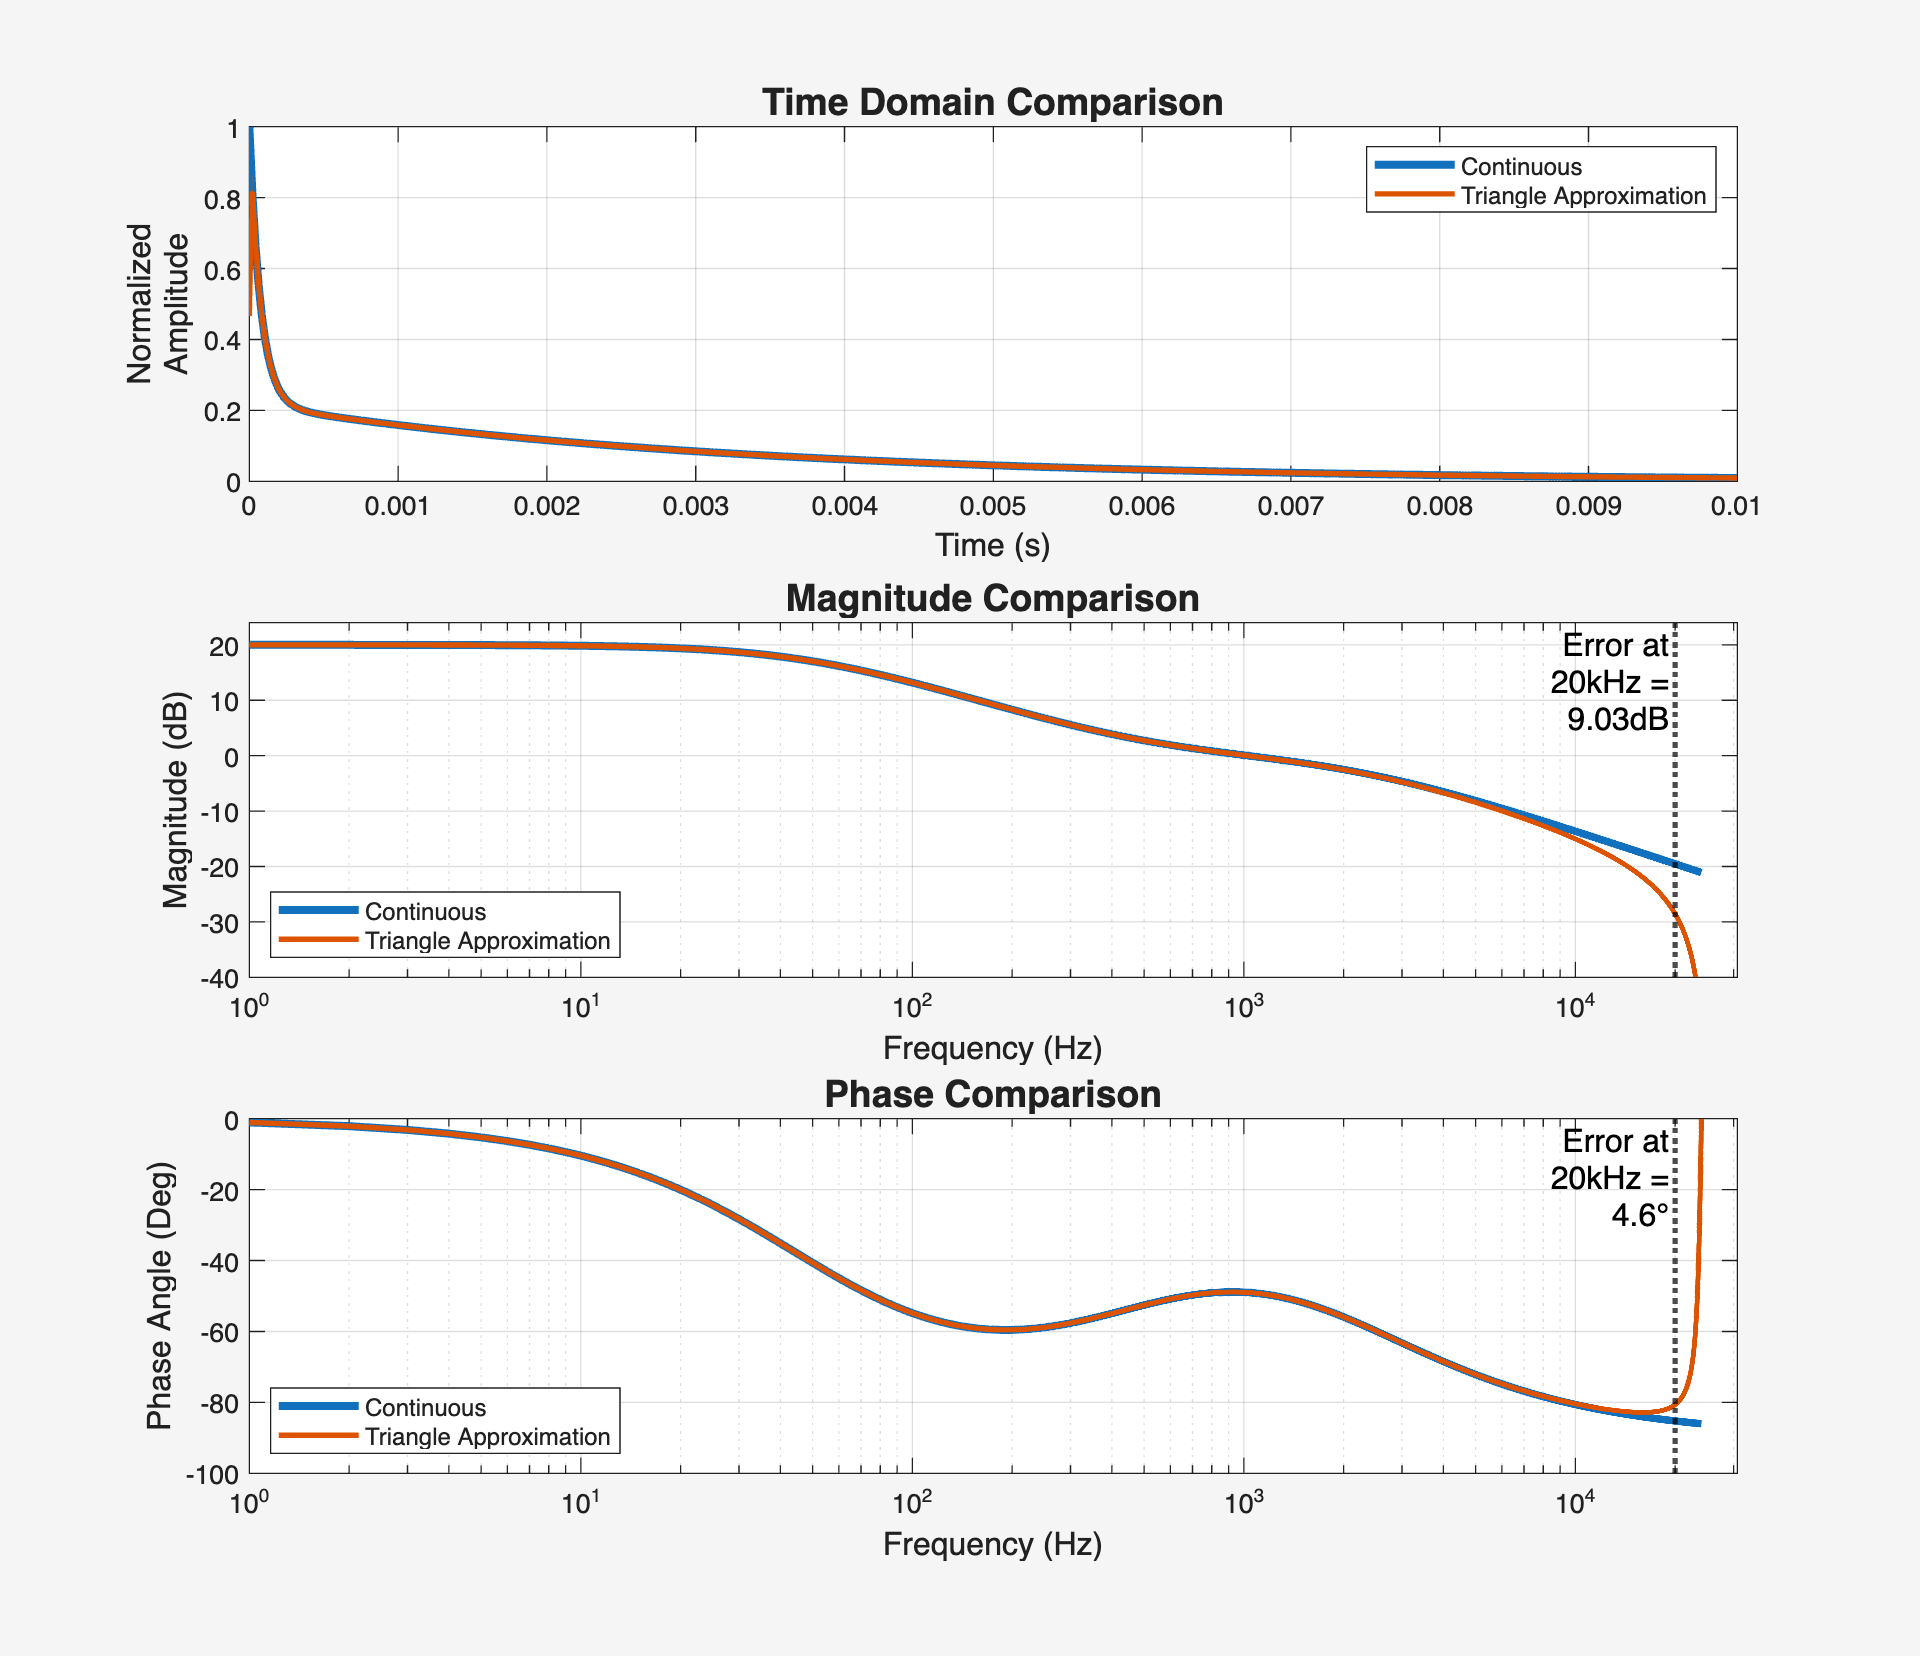

% frequency domain plots
% magFig = figure(4);
% magAxes = axes(magFig);
% set(magFig, 'CurrentAxes', magAxes)
% set(0, 'CurrentFigure', magFig)

subplot(3,1,2)
semilogx(f,mag2db(abs(H0)),LineWidth=3)
title("Magnitude Comparison",fontsize=titleFontSize)
hold on
semilogx(f,mag2db(abs(H1)),LineWidth=2)
xline(testFreq,LineWidth=2,Label=['Error at' newline '20kHz =' newline num2str(magError,'%.2f') ...
    'dB'],Color='k',LineStyle=':',FontSize=annotationFontSize,LabelOrientation='horizontal',...
    LabelHorizontalAlignment='left',LabelVerticalAlignment='top')
hold off
legend(legendStr, Location='southwest')
xlabel("Frequency (Hz)",fontsize=labelFontSize)
ylabel("Magnitude (dB)",fontsize=labelFontSize)
xlim([0 fs/2+0.1*fs+2000])
ylim([-40 24])
grid on


% phaseFig = figure(5);
% phaseAxes = axes(phaseFig);
% set(phaseFig, 'CurrentAxes', phaseAxes)
% set(0, 'CurrentFigure', phaseFig)
subplot(3,1,3)
semilogx(f,rad2deg(angle(H0)),LineWidth=3)
hold on
semilogx(f,rad2deg(H1ang),LineWidth=2)
title("Phase Comparison", fontsize=titleFontSize)
xline(testFreq,LineWidth=2,Label=['Error at' newline '20kHz =' newline num2str(phaseError,'%.1f') char(176) newline newline newline], ...
    Color='k',LineStyle=':',FontSize=annotationFontSize,LabelOrientation='horizontal',...
    LabelHorizontalAlignment='left',LabelVerticalAlignment='top')
hold off
legend(legendStr, Location='southwest')
xlim([0 fs/2+0.1*fs+2000])
xlabel("Frequency (Hz)",fontsize=labelFontSize)
ylabel("Phase Angle (Deg)",fontsize=labelFontSize)
grid on

responseFig.Units = "inches";
responseFig.Position = [1 1 10 10];
set(responseFig,'Visible','on')


disp(['Bark-Weighted Magnitude RMSE (20Hz-20kHz)  = ' num2str(rootMeanSqMagErrorWeighted,'%.2f') ' dB'])

Bark-Weighted Magnitude RMSE (20Hz-20kHz)  = 1.41 dB


disp(['Bark-Weighted Phase RMSE (20Hz-20kHz) = ' num2str(rootMeanSqPhaseErrorWeighted,'%.2f') ' ' char(176)])

Bark-Weighted Phase RMSE (20Hz-20kHz) = 0.51 °


### 6.1) Discussion of Results

At this point, it is recommended to vary the both the discretization method and the oversampling factor, and see what methods result in more accurate playback equalization filters based on the metrics shown in the previous section. The table of results reported in the paper (Table 1) can be repeated using the above sections of the Live Script for each discritzation method. That table is reproduced here:

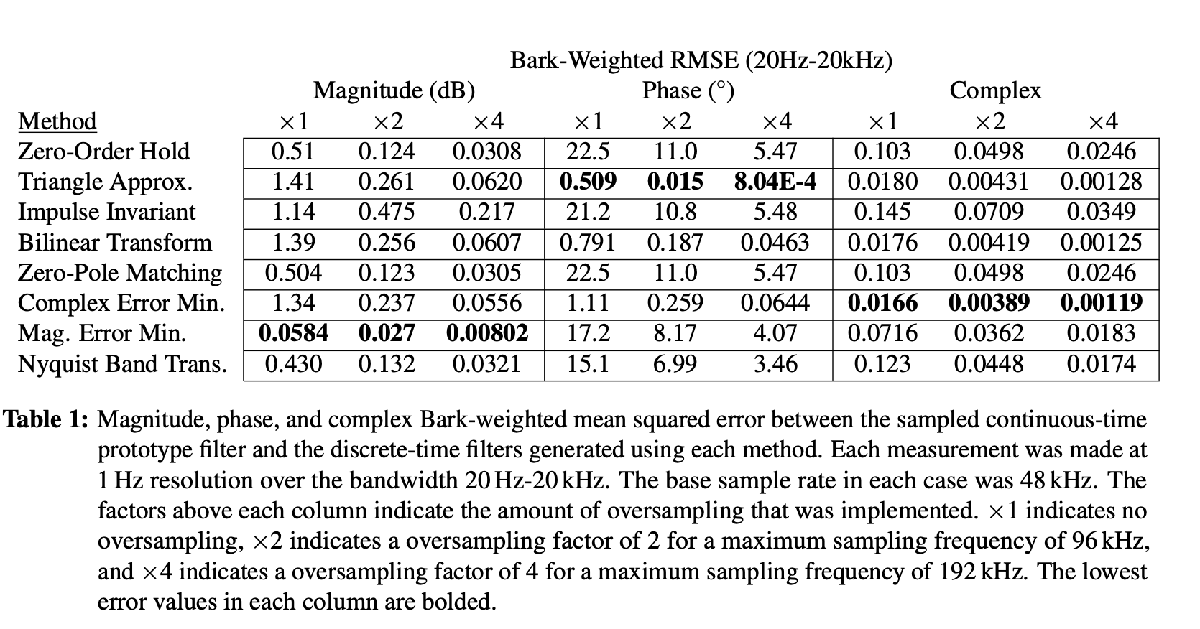

The lowest magnitude, phase, and complex errors were achieved by the Magnitude Error Minimization, Triangle Approximation, and Complex Error Minimization methods, respectively. The first and third results are unsurprising as these methods iteratively minimize an error metric that is related to the ones that we are using for evaluation. While these methods are highly accurate, they are the most computationally expensive of the methods, and are therefore potentially unsuitable for some real-time applications. Of the non-iterative methods, the NBT exhibits the lowest magnitude error with no oversampling, and Zero-Pole Matching achieves the lowest error when oversampling is implemented. In terms of complex accuracy, of the non-iterative methods, the Bilinear Transform exhibits the lowest error. For each method, it is also apparent that all three metrics are improved as the oversampling factor is increased. 

## 7) Listen to The Results

In this section you can apply the filter you just created to an audio file, and then listen to the result. The test audio is excerpted from 'Enchantment' by The Melody Mates released in 1960. It was recorded at 48kHz both flat and with analog RIAA playabck equalization applied. 

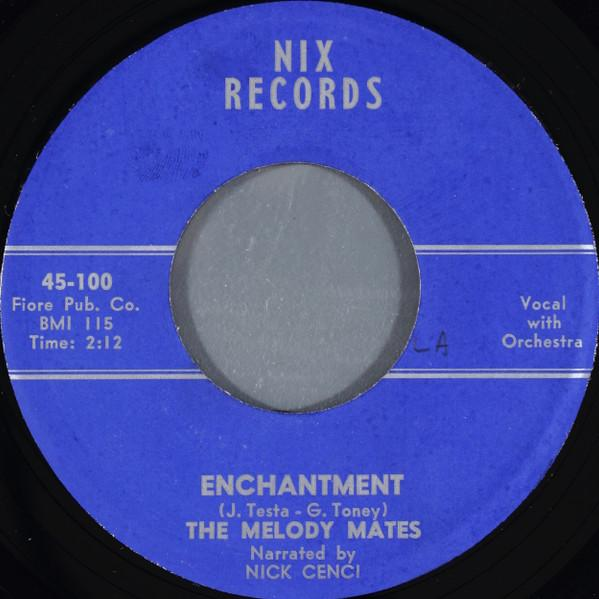

Click the 'Apply Filter' button below to filter the provided test audio with the RIAA playback filter created above.

 

[fixedTestAudioFlat, fsFixedTestAudio] = audioread("assets/fixedTestAudioFlat.wav"); % read in fixed test audio
fixedTestAudioFiltered = fixedTestAudioFlat;

% upsample
for stage = 1:overSampleExp
    fixedTestAudioFiltered = upFilts{stage}(fixedTestAudioFiltered); 
end

fixedTestAudioFiltered = filter(b1,a1,fixedTestAudioFiltered); % filter 

% downsample
for stage = overSampleExp:-1:1
    fixedTestAudioFiltered = downFilts{stage}(fixedTestAudioFiltered); 
end

Listen to the provided test audio with **no filter** applied.

 
 clear sound
 sound(fixedTestAudioFlat,fsFixedTestAudio)

Listen to the provided test audio with the **discretized RIAA playback filter **applied.

 
clear sound
sound(fixedTestAudioFiltered,fsFixedTestAudio)

Listen to a version of the provided test audio prerecorded with an **analog RIAA playback filter** applied. Note that this was produced with an **analog filter made from physical components with tolerances! **The response of this fiter is unlikely to adhere to the ideal RIAA magnitude response with better than +/-0.5dB accuracy, so bear that in mind when making comparisons to the discretized version. 

 
clear sound
[fixedTestAudioAnalog, fsFixedTestAudioAnalog] = audioread("assets/fixedTestAudioRIAA.wav"); % read in fixed test audio
sound(fixedTestAudioAnalog,fsFixedTestAudioAnalog)

 
clear sound

## 8) Helper Functions

In this section, we define helper functions for many of the discritization methods shown above:

### 8.1) getOverSamplingFilters

function [upFilts, downFilts] = getOverSamplingFilters(numStages)

    upFilts = cell(numStages,1);
    downFilts = cell(numStages,1);

    for stage = 1:numStages    
        if stage == 1
            twUp = single(0.05);
            twDown = single(0.06);
        else
            twUp = single(0.10);
            twDown = single(0.12);
        end
        
        gaindBStartUp    = -90.0;
        gaindBStartDown  = -75.0;
        gaindBFactorUp   =  10.0;
        gaindBFactorDown =  10.0;
        
        SBAup=gaindBStartUp + gaindBFactorUp * (stage-1);
        SBAdown=gaindBStartDown + gaindBFactorDown * (stage-1);

        upFilts{stage} = getUpFilts(SBAup,twUp);
        downFilts{stage} = getDownFilts(SBAdown, twDown);

    end
end

### 8.2) getUpFilts

function [c] = getUpFilts(amplitudedB, normalisedTransitionWidth)
    c = designHalfbandFIR(TransitionWidth=normalisedTransitionWidth, ...
                            StopbandAttenuation=-1*amplitudedB, SystemObject=true, ...
                            Structure='interp', DesignMethod="equiripple", Verbose=true);
end



### 8.3) getDownFilts

%%
function [c] = getDownFilts(amplitudedB, normalisedTransitionWidth)
    c = designHalfbandFIR(TransitionWidth=normalisedTransitionWidth, ...
                            StopbandAttenuation=-1*amplitudedB, SystemObject=true, ...
                            Structure='decim', DesignMethod="equiripple", Verbose=true);
end


### 8.4) invFreqzMagOnly

function [b, a] = invFreqzMagOnly(bs, as, fs, Nfft, NZ, NP)

% bs: s-domain numerator 
% as: s-domain denominator 
% fs: sample rate for discritization 
% Nfft: fft length (number of frequencies at which to sample
    % analog freq response including negative frequencies)
% Nz: desired number of zeros
% Np: desired number of poles

% Adapted from "Physical Audio Signal Processing" by Julius Orion Smith III, November 8, 2010
% https://www.dsprelated.com/freebooks/pasp/Fitting_Filters_Measured_Amplitude.html

    fk = fs*[0:Nfft/2]/Nfft; % fft frequency grid (nonneg freqs)
    radPerSec = 2*pi*fk;
    H0 = freqs(bs,as,radPerSec); % analog frequency response sampled at fk  
    Gfk = abs(H0);
    Ns = length(Gfk);

    S = [Gfk,Gfk(Ns-1:-1:2)]; % install negative-frequencies
    Sdb = mag2db(S);

    c = ifft(Sdb); % compute real cepstrum from log magnitude spectrum
    % Fold cepstrum to reflect non-min-phase zeros inside unit circle:
    cf = [c(1), c(2:Ns-1)+c(Nfft:-1:Ns+1), c(Ns), zeros(1,Nfft-Ns)];
    Cf = fft(cf); % = dB_magnitude + j * minimum_phase
    Smp = 10 .^ (Cf/20); % minimum-phase spectrum
    
    Smpp = Smp(1:Ns); % nonnegative-frequency portion
    % wt = 1 ./ (fk+1); % typical weight fn for audio
    wk = 2*pi*fk/fs;
    wt = getBkWts(fk);
    [b,a] = invfreqz(Smpp,wk,NZ,NP,wt,1e3,1e-6);

end

### 8.5) nyquistBandTransform

function [b, a, compTime] = nyquistBandTransform(bs, as, fs, order)
% Returns a discritized version of the continous-time filter, bs/as. The
% discritization is carried out using the Nyquist band transform devloped
% in Nyquist Band Transform: An Order-Preserving Transform for Bandlimited
% Discretization by CHAMP C. DARABUNDIT, JONATHAN S. ABEL, and DAVID
% BERNERS found at
% https://ccrma.stanford.edu/~champ/files/Darabundit2022_NBT.pdf

% bs: s-domain numerator 
% as: s-domain denominator 
% fs: sample rate for discritization 
% order: order of bs, as - these should be the same, zero pad if necessary

% b: z-domain numerator
% a: z-domain denominator
% compTime: computation time excluding matrix construction which could be
% pre-computed in many use cases

    N = order;
    Omega0 = pi*fs; % nyquist frequency in rad/sec
    T = 1/fs; % sample period 

    % EQ. 39 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization with modification: "The formulation in Eq.
    % (39) can also be used to apply the first transform Eq. (26) by swapping
    % Omega0^2 for -Omega0^2 and replacing gamma with −2*Omega0*OmegaC". OmegaC is
    % set equal to Omega0
    A0 = zeros(2*N+1,N+1);
    for n = 0:N
        for k = 0:n
            A0(N-n+2*k+1,(n+1)) = (-2*Omega0^2)^(N-n)*nchoosek(n,k)*(-1*Omega0^2)^(n-k);
        end
    end
    
    A0 = flip(A0,1);

    % gamma is a free paramater that allows perfect matching for one
    % frequency via EQ. 64 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization
    % Uplsilon = 2*(((2/T)*tan((Omega_a*T)/2))/Omega_a)*sqrt(1-((Omega_a*T)/pi)^2);
    
    % "If there is no a priori of the system, a possible choice for γ is to set
    % Omega_a = (π*fs)/2: half the Nyquist limit. This results in a γ =
    % 4*(3^0.5)*π*fs^2 ≈ 2.2*Omega0^2"    
    % gamma = 2.2*Omega0^2;

    % Alternately, gamma can be optimized to give the smallest amount of
    % frequency warping accross some bandwidth with some weighting. The
    % following values are optimized to give the least mean absolute error
    % in frequency mapping from 20Hz-20kHz for each sample rate:

    % Bark-Weighted MSE, 20Hz-20kHz
    switch fs
        case 48e3
            gammaHat = 2.1826;
        case 96e3 
            gammaHat = 2.0532;
        case 192e3 
            gammaHat = 2.0130;
        case 384e3 
            gammaHat = 2.0032;
        case 768e3 
            gammaHat = 2.0008;
        otherwise
            gammaHat = 2;    
    end

    gamma = gammaHat*Omega0^2;

    % EQ. 39 in Nyquist Band Transform: An Order-Preserving Transform for
    % Bandlimited Discretization.
    % OmegaC is set equal to Omega0
    A = zeros(2*N+1,N+1);
    for n = 0:N
        for k = 0:n
            A(N-n+2*k+1,(n+1)) = (gamma)^(N-n)*nchoosek(n,k)*(Omega0^2)^(n-k);
        end
    end
    
    A = flip(A,1);
    
    Aplus = pinv(A);

    tic;
    
    % first forward transform
    kb = A0*bs.'; 
    ka = A0*as.';

    % Stabilize the mapped coefficients κa and enforce minimum/maximum phase
    % on κb
    [z,p,k] = tf2zp(kb.',ka.');
    pImag = imag(p);
    pReal = real(p);
    pRealStable = abs(pReal)*-1;
    pStable = pRealStable+pImag;
    
    zImag = imag(z);
    zReal = real(z);
    zRealStable = abs(zReal)*-1;
    zMinPhase = zRealStable+zImag;
    
    [kbStable, kaStable] = zp2tf(zMinPhase,pStable,k);

    % second inverse transform
    cb = Aplus*kbStable.';
    ca = Aplus*kaStable.';

    % bilinear transform
    sdtf = tf(cb.', ca.');
    opts = c2dOptions;
    opts.Method = 'tustin';
    zdtf = c2d(sdtf,T,opts);

    % discrete time coefficients 
    b = zdtf.Numerator{1}; 
    a = zdtf.Denominator{1};  

    compTime = toc;
end

### 8.6) getBkWts

function bkWts = getBkWts(freq)
    % Returns an array of weights the same length as freq where each weight
    % equals 1 divided by the bandwidth of the Bark band that the
    % corresponding frequency falls in for frequencies less than 27kHz and
    % 1/f for frequencies above that.
    
    % freq: An array of frequencies in Hz

    barkBandEdges = [20, 100, 200, 300, 400, 510, ...
        630, 770, 920, 1080, 1270, 1480, 1720, ...
        2000, 2320, 2700, 3150, 3700, 4400, 5300, ...
        6400, 7700, 9500, 12000, 15500, 20500, 27001];

    if any(freq < 0)
        error("min frequency = 0 Hz")
    end

    % make array of bandwidths corresponding to each Bark band
    barkBandWidths = zeros(length(barkBandEdges)-1,1);
    for idx = 1:length(barkBandWidths)
        barkBandWidths(idx) = barkBandEdges(idx+1)-barkBandEdges(idx);
    end

    bkWts = zeros(length(freq),1);

    % for each frequency, find the Bark band that it falls into and fill the
    % corresponding index in bkWts with 1 divided by the bandwidth of that
    % band
    for idx = 1:length(bkWts)
        if freq(idx) < barkBandEdges(2)
            bkWts(idx) = 1/barkBandWidths(1);    
        elseif freq(idx) < barkBandEdges(3)
            bkWts(idx) = 1/barkBandWidths(2);
        elseif freq(idx) < barkBandEdges(4)
            bkWts(idx) = 1/barkBandWidths(3);        
        elseif freq(idx) < barkBandEdges(5)
            bkWts(idx) = 1/barkBandWidths(4);
        elseif freq(idx) < barkBandEdges(6)
            bkWts(idx) = 1/barkBandWidths(5);        
        elseif freq(idx) < barkBandEdges(7)
            bkWts(idx) = 1/barkBandWidths(6);
        elseif freq(idx) < barkBandEdges(8)
            bkWts(idx) = 1/barkBandWidths(7);
        elseif freq(idx) < barkBandEdges(9)
            bkWts(idx) = 1/barkBandWidths(8);
        elseif freq(idx) < barkBandEdges(10)
            bkWts(idx) = 1/barkBandWidths(9);
        elseif freq(idx) < barkBandEdges(11)
            bkWts(idx) = 1/barkBandWidths(10);
        elseif freq(idx) < barkBandEdges(12)
            bkWts(idx) = 1/barkBandWidths(11);
        elseif freq(idx) < barkBandEdges(13)
            bkWts(idx) = 1/barkBandWidths(12);
        elseif freq(idx) < barkBandEdges(14)
            bkWts(idx) = 1/barkBandWidths(13);
        elseif freq(idx) < barkBandEdges(15)
            bkWts(idx) = 1/barkBandWidths(14);
        elseif freq(idx) < barkBandEdges(16)
            bkWts(idx) = 1/barkBandWidths(15);
        elseif freq(idx) < barkBandEdges(17)
            bkWts(idx) = 1/barkBandWidths(16);
        elseif freq(idx) < barkBandEdges(18)
            bkWts(idx) = 1/barkBandWidths(17);
        elseif freq(idx) < barkBandEdges(19)
            bkWts(idx) = 1/barkBandWidths(18);
        elseif freq(idx) < barkBandEdges(20)
            bkWts(idx) = 1/barkBandWidths(19);
        elseif freq(idx) < barkBandEdges(21)
            bkWts(idx) = 1/barkBandWidths(20);
        elseif freq(idx) < barkBandEdges(22)
            bkWts(idx) = 1/barkBandWidths(21);
        elseif freq(idx) < barkBandEdges(23)
            bkWts(idx) = 1/barkBandWidths(22);
        elseif freq(idx) < barkBandEdges(24)
            bkWts(idx) = 1/barkBandWidths(23);
        elseif freq(idx) < barkBandEdges(25)
            bkWts(idx) = 1/barkBandWidths(24);
        elseif freq(idx) < barkBandEdges(26)
            bkWts(idx) = 1/barkBandWidths(25);
        elseif freq(idx) < barkBandEdges(27)
            bkWts(idx) = 1/barkBandWidths(26);
        else 
            bkWts(idx) = 1/(freq(idx)); % 1/f weighting for everything else
        end
    end
end

### 8.7) userFeedback


function [fileName] = userFeedback(transformMethod)
    % 0: Zero-Order Hold
    % 1: Triangle Approximation
    % 2: Impulse Invariant 
    % 3: Bilinear
    % 4: Zero-Pole Matching
    % 5: Curve Fitting (Complex)
    % 6: Curve Fitting (Magnitude Only) 
    % 7: Nyquist Band Transform

    % addpath('assets/');

    switch transformMethod
        case 0
            %Zoh
            fileName = 'Method0.png';
        case 1
            %Triangle
            fileName = 'Method1.png';
        case 2
            % Impulse
            fileName = 'Method2.png';
        case 3
            % Bilinear
            fileName = 'Method3.png';
        case 4
            %ZPMatching  
            fileName = 'Method4.png';
        case 5
            % Complex Curve Fitting
            fileName = 'Method5.png';
        case 6
            % Curve Fitting Magnitude
            fileName = 'Method6.png';
        case 7
            % Nyquist band transform
            fileName = 'Method7.png';
    end 
end